## Analyze Quality of Life in U.S. Cities Using PCA

### **Load sample data.**

load cities
categories

categories = 9×14 char array
    'climate       '
    'housing       '
    'health        '
    'crime         '
    'transportation'
    'education     '
    'arts          '
    'recreation    '
    'economics     '


names

names = 329×43 char array
    'Abilene, TX                                '
    'Akron, OH                                  '
    'Albany, GA                                 '
    'Albany-Troy, NY                            '
    'Albuquerque, NM                            '
    'Alexandria, LA                             '
    'Allentown,Bethlehem, PA-NJ                 '
    'Alton, Granite City, IL                    '
    'Altoona, PA                                '
    'Amarillo, TX                               '
    'Anaheim-Santa Ana, CA                      '
    'Anchorage, AK                              '
    'Anderson, IN                               '
    'Anderson, SC                               '
    'Ann Arbor, MI                              '
    'Anniston, AL                               '
    'Appleton-Oshkosh-Neenah, WI                '
    'Asheville, NC                              '
    'Athens, GA                                 '
    'Atlanta, GA        

ratings

ratings =          521        6200         237         923        4031        2757         996        1405        7633
         575        8138        1656         886        4883        2438        5564        2632        4350
         468        7339         618         970        2531        2560         237         859        5250
         476        7908        1431         610        6883        3399        4655        1617        5864
         659        8393        1853        1483        6558        3026        4496        2612        5727
         520        5819         640         727        2444        2972         334        1018        5254
         559        8288         621         514        2881        3144        2333        1117        5097
         537        6487         965         706        4975        2945        1487        1280        5795
         561        6191         432         399        4246        2778         256        1210        4230
         

#### Plot

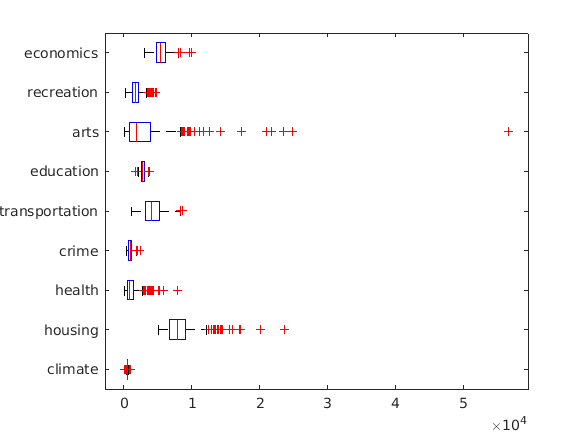

figure()
boxplot(ratings,'Orientation','horizontal','Labels',categories)

### Correlation check

C = corr(ratings,ratings)

C =     1.0000    0.3863    0.2133    0.1924    0.0791    0.0645    0.2270    0.2135   -0.1001
    0.3863    1.0000    0.4530    0.1342    0.2719    0.1979    0.4486    0.4223    0.2694
    0.2133    0.4530    1.0000    0.3047    0.4703    0.4902    0.8658    0.3254    0.0693
    0.1924    0.1342    0.3047    1.0000    0.2866    0.0744    0.3895    0.3446    0.2600
    0.0791    0.2719    0.4703    0.2866    1.0000    0.3360    0.4648    0.3647    0.0592
    0.0645    0.1979    0.4902    0.0744    0.3360    1.0000    0.3733    0.0778    0.1197
    0.2270    0.4486    0.8658    0.3895    0.4648    0.3733    1.0000    0.3787    0.0757
    0.2135    0.4223    0.3254    0.3446    0.3647    0.0778    0.3787    1.0000    0.1735
   -0.1001    0.2694    0.0693    0.2600    0.0592    0.1197    0.0757    0.1735    1.0000


w = 1./var(ratings);
[wcoeff,score,latent,tsquared,explained] = pca(ratings,...
'VariableWeights',w);

### Sections

c3 = wcoeff(:,1:3)

c3 = 	1.0e+03 *

    0.0249   -0.0263   -0.0834
    0.8504   -0.5978   -0.4965
    0.4616    0.3004   -0.0073
    0.1005   -0.1269    0.0661
    0.5096    0.2606    0.2124
    0.0883    0.1551    0.0737
    2.1496    0.9043   -0.1229
    0.2649   -0.3106   -0.0411
    0.1469   -0.5111    0.6586


 coefforth = inv(diag(std(ratings)))*wcoeff;

I = coefforth'*coefforth;
I(1:3,1:3)

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


cscores = zscore(ratings)*coefforth;

figure()
plot(score(:,1),score(:,2),'+')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
gname

metro = [43 65 179 213 234 270 314];
names(metro,:)

ans = 7×43 char array
    'Boston, MA                                 '
    'Chicago, IL                                '
    'Los Angeles, Long Beach, CA                '
    'New York, NY                               '
    'Philadelphia, PA-NJ                        '
    'San Francisco, CA                          '
    'Washington, DC-MD-VA                       '


latent,explained

latent =     3.4083
    1.2140
    1.1415
    0.9209
    0.7533
    0.6306
    0.4930
    0.3180
    0.1204


explained =    37.8699
   13.4886
   12.6831
   10.2324
    8.3698
    7.0062
    5.4783
    3.5338
    1.3378


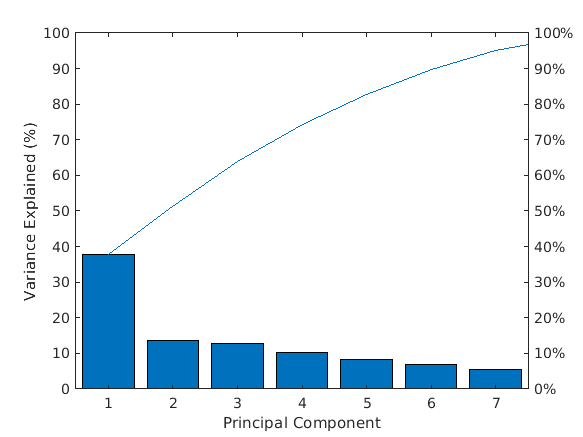

figure()
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

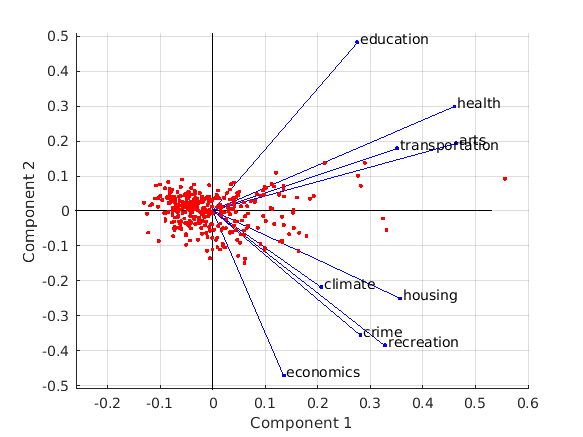

biplot(coefforth(:,1:2),'Scores',score(:,1:2),'Varlabels',categories);
axis([-.26 0.6 -.51 .51]);

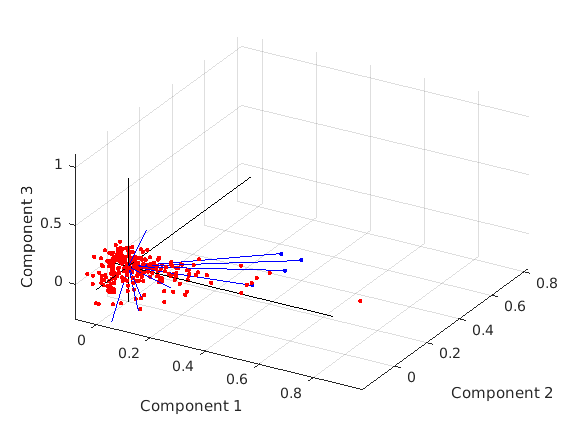

figure()
biplot(coefforth(:,1:3),'Scores',score(:,1:3),'Obslabels',names);
axis([-.26 0.8 -.51 .51 -.61 .81]);
view([30 40]);